## Code for training EEG and EMG classifiers

#### Load data

raw_eeg_data = load("data_sets\eeg_test.txt");
eeg_fs=200; % EEG sample rate
raw_emg_data = load("data_sets\emg_test.txt");
emg_fs=1000; % EMG sample rate

#### Display data lost

EEG

fprintf("=======================================================================================")

data_lost = 0;
expected_data = length(raw_eeg_data);
for i = 2:length(raw_eeg_data)
    if raw_eeg_data(i,1) ~= mod(raw_eeg_data(i-1,1) + 1, 200)
        data_lost = data_lost + 1;
    end
end
disp(['EEG Data lost: ', num2str((data_lost/expected_data)*100,'%.2f'),'%']);

EEG Data lost: 51.23%


EMG

data_lost = 0;
expected_data = length(raw_emg_data);
for i = 2:length(raw_emg_data)
    if raw_emg_data(i,4) ~= mod(raw_emg_data(i-1,4) + 1, 1000)
        data_lost = data_lost + 1;
    end
end
disp(['EMG Data lost: ', num2str((data_lost/expected_data)*100,'%.2f'),'%']);

EMG Data lost: 0.00%


fprintf("=======================================================================================")

#### Display data quality

EEG

fprintf("=======================================================================================")

% Extract signal-to-noise (SNR), signal to noise and distortion ratio (SINAD), total harmonic distortion (THD).
sFE = signalTimeFeatureExtractor(SampleRate=eeg_fs, SNR = true, SINAD = true, THD = true);
fprintf("EEG data quality")

EEG data quality

eeg_quality = extract(sFE,raw_eeg_data);
fprintf('\nChannel 1:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',eeg_quality(:,1,2),eeg_quality(:,2,2), eeg_quality(:,3,2));


Channel 1:
SNR:	 -2.292611
SINAD:	 3.720979
THD:	 -4.991954


fprintf('\nChannel 2:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',eeg_quality(:,1,3),eeg_quality(:,2,3), eeg_quality(:,3,3));


Channel 2:
SNR:	 15.386040
SINAD:	 -5.392003
THD:	 15.386040


fprintf('\nChannel 3:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',eeg_quality(:,1,4),eeg_quality(:,2,4), eeg_quality(:,3,4));


Channel 3:
SNR:	 4.187795
SINAD:	 1.192124
THD:	 -1.893870


fprintf('\nChannel 4:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',eeg_quality(:,1,5),eeg_quality(:,2,5), eeg_quality(:,3,5));


Channel 4:
SNR:	 -3.468271
SINAD:	 -6.315733
THD:	 -3.887220


EMG

fprintf("EMG data quality")

EMG data quality

emg_quality = extract(sFE,raw_emg_data);
fprintf('\nChannel 1:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',emg_quality(:,1,1),emg_quality(:,2,1), emg_quality(:,3,1));


Channel 1:
SNR:	 10.416186
SINAD:	 -19.144057
THD:	 9.876251


fprintf('\nChannel 2:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',emg_quality(:,1,2),emg_quality(:,2,2), emg_quality(:,3,2));


Channel 2:
SNR:	 10.404548
SINAD:	 -19.109593
THD:	 9.855891


fprintf("=======================================================================================")

#### Visualize signal

EEG

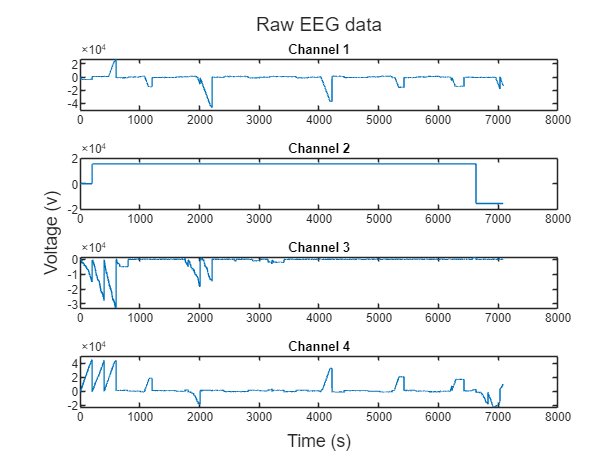

% Plot all EEG channels
figure
EEG_plot_handle = tiledlayout(4,1);
channel1_plot_handle = nexttile;
plot(raw_eeg_data(:,2))
title('Channel 1')
channel2_plot_handle = nexttile;
plot(raw_eeg_data(:,3))
title('Channel 2')
channel3_plot_handle = nexttile;
plot(raw_eeg_data(:,4))
title('Channel 3')
channel4_plot_handle = nexttile;
plot(raw_eeg_data(:,5))
title('Channel 4')

% Link x axis
linkaxes([channel1_plot_handle,channel2_plot_handle,channel3_plot_handle,channel4_plot_handle],'x');

% Add title etc
title(EEG_plot_handle,'Raw EEG data')
xlabel(EEG_plot_handle,'Time (s)')
ylabel(EEG_plot_handle,'Voltage (v)')

EMG

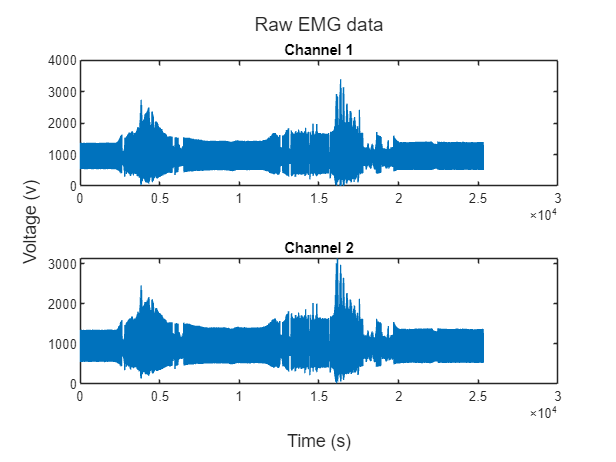

% Plot all EMG channels
figure
EMG_plot_handle = tiledlayout(2,1);
channel1_plot_handle = nexttile;
plot(raw_emg_data(:,1))
title('Channel 1')
channel2_plot_handle = nexttile;
plot(raw_emg_data(:,2))
title('Channel 2')

% Link x axis
linkaxes([channel1_plot_handle,channel2_plot_handle],'x');

% Add title etc
title(EMG_plot_handle,'Raw EMG data')
xlabel(EMG_plot_handle,'Time (s)')
ylabel(EMG_plot_handle,'Voltage (v)')

fprintf("=======================================================================================")

#### Preprocessing

EEG

Artifact removal: [https://se.mathworks.com/matlabcentral/fileexchange/55413-wica-data-varargin](https://se.mathworks.com/matlabcentral/fileexchange/55413-wica-data-varargin) 

Dependency: [https://github.com/biotrump/RADICAL-matlab](https://github.com/biotrump/RADICAL-matlab) 

Dependency: [https://research.ics.aalto.fi/ica/fastica/](https://research.ics.aalto.fi/ica/fastica/) 

% Remove artifacts from EEG using wavelet enhanced ICA, W-ICA
[wIC,A,W,IC] = wICA(transpose(raw_eeg_data(:,[2,3,4,5])));

Number of signals: 4
Number of samples: 7089
Calculating covariance...
Dimension not reduced.
Selected [ 4 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 1.29838e+07 ]
Largest remaining (non-zero) eigenvalue [ 1.10916e+08 ]
Sum of removed eigenvalues [ 0 ]
[ 100 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 1.55431e-15 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 .......computed ( 7 steps ) 
IC 2 ......computed ( 6 steps ) 
IC 3 ..........computed ( 10 steps ) 
IC 4 ..computed ( 2 steps ) 
Done.
Adding the mean back to the data.
Perforing wavelet thresholding


% Artifacts
artifacts = transpose(A*wIC);
% Subtract artifacts from original signal to get "artifact free" signal
filtered_eeg_data = raw_eeg_data(:,[2,3,4,5]) - artifacts;

%--------------------------------------------------------------------------------------------------------
%{
%{
% Median filtering of the baseline wandering which usually is of a frequency of about 0.5Hz, but can be higher with movement.
% Baseline wandering is usually caused by respiration, electrodes(like poor contact or internal changes) and motion.
% The values 24 and 80 is for a sampling frequency of 500Hz.
s_filt_1=medfilt1(data,(eeg_fs/500)*24);
s_filt_2=medfilt1(s_filt_1,(eeg_fs/500)*80);
filtered_eeg_data = raw_eeg_data - s_filt_2;
%}

% Remove baseline wandering and DC offset
% 4th order Butterworth highpass filter 0.1hz cut off frequency.
[n,d] = butter(4,(0.1)/(eeg_fs/2),"high");
filtered_eeg_data = filter(n,d,raw_eeg_data);

% Removal of 50Hz noise and all of it's harmonics up to 100Hz. 
% The noise is caused by magnetic fields generated by powerlines.
% Using a IIR notch filter of the fourth order as it's at that point the 50Hz noise peak on most signals practicaly becomes zero if a quality factor of about 25-35 is being used.
fo = 4;     % Filter order.
cf = 50/(eeg_fs/2); % Center frequency, value has to be between 0 and 1, where 1 is pi which is the Nyquist frequency which for our signal is Fs/2 = 500Hz.
qf = 30;   % Quality factor.
pbr = 1;   % Passband ripple, dB.
for k = 1:2
    notchSpecs  = fdesign.notch('N,F0,Q,Ap',fo,cf * k,qf,pbr);
    notchFilt = design(notchSpecs,'IIR','SystemObject',true);
    filtered_eeg_data = notchFilt(filtered_eeg_data); 
end
%}

% 1. package ID
% 2. 3. 4. 5. channel 1,2,3,4, 
% 5. timestamp
filtered_eeg_data = [raw_eeg_data(:,1) filtered_eeg_data raw_eeg_data(:,14)];

%--------------------------------------------------------------------------------------------------------

fprintf("=======================================================================================")

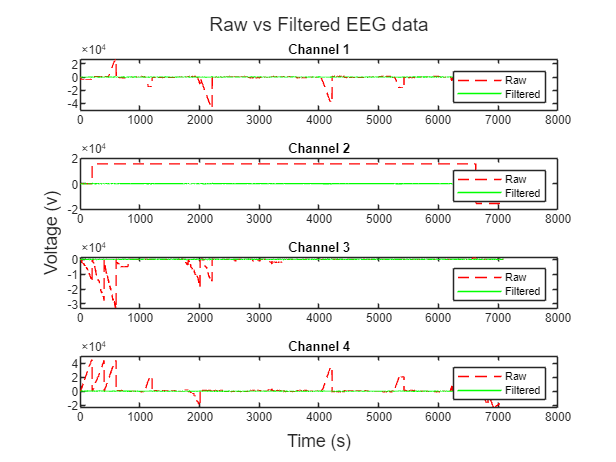

% Plot all EEG channels
figure
EEG_filtered_plot_handle = tiledlayout("vertical");
channel1_filtered_plot_handle = nexttile;
plot(raw_eeg_data(:,2), 'r--')
hold on
plot(filtered_eeg_data(:,2), 'g')
hold off
title('Channel 1')
legend('Raw','Filtered')
channel2_filtered_plot_handle = nexttile;
plot(raw_eeg_data(:,3), 'r--')
hold on
plot(filtered_eeg_data(:,3), 'g')
hold off
title('Channel 2')
legend('Raw','Filtered')
channel3_filtered_plot_handle = nexttile;
plot(raw_eeg_data(:,4), 'r--')
hold on
plot(filtered_eeg_data(:,4), 'g')
hold off
title('Channel 3')
legend('Raw','Filtered')
channel4_filtered_plot_handle = nexttile;
plot(raw_eeg_data(:,5), 'r--')
hold on
plot(filtered_eeg_data(:,5), 'g')
hold off
title('Channel 4')
legend('Raw','Filtered')

% Link x axis
linkaxes([channel1_filtered_plot_handle,channel2_filtered_plot_handle,channel3_filtered_plot_handle,channel4_filtered_plot_handle],'x');

% Add title etc
title(EEG_filtered_plot_handle,'Raw vs Filtered EEG data')
xlabel(EEG_filtered_plot_handle,'Time (s)')
ylabel(EEG_filtered_plot_handle,'Voltage (v)')

EMG

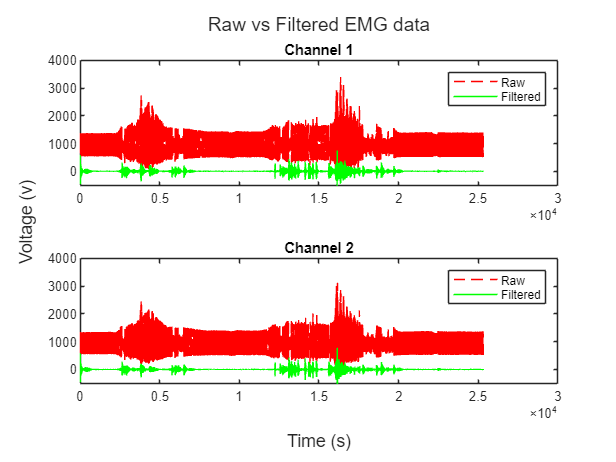

% Removal of the 0Hz(the DC offset) and high frequency noise.
% 20–500Hz fourth-order Butterworth bandpass filter.
[n,d] = butter(4,[20 499]/(emg_fs/2),"bandpass");
filtered_emg_data = filter(n,d,raw_emg_data(:,[1,2]));

% Removal of 50Hz noise and all of it's harmonics up to 150Hz. 
% The noise is caused by magnetic fields generated by powerlines.
% Using a IIR notch filter of the fourth order as it's at that point the 50Hz noise peak on most signals practicaly becomes zero if a quality factor of about 25-35 is being used.
fo = 4;     % Filter order.
cf = 50/(emg_fs/2); % Center frequency, value has to be between 0 and 1, where 1 is pi which is the Nyquist frequency which for our signal is Fs/2 = 500Hz.
qf = 30;   % Quality factor.
pbr = 1;   % Passband ripple, dB.
for k = 1:3
    notchSpecs  = fdesign.notch('N,F0,Q,Ap',fo,cf * k,qf,pbr);
    notchFilt = design(notchSpecs,'IIR','SystemObject',true);
    filtered_emg_data = notchFilt(filtered_emg_data); 
end

% 1. package ID
% 2. 3. channel 1,2
% 4. Label
% 5. time stamp
filtered_emg_data = [raw_emg_data(:,4) filtered_emg_data raw_emg_data(:,3) raw_emg_data(:,5)];

%--------------------------------------------------------------------------------------------------------

% Plot all EMG channels
figure
EMG_plot_handle = tiledlayout(2,1);
channel1_filtered_plot_handle = nexttile;
plot(raw_emg_data(:,1),'r--')
hold on
plot(filtered_emg_data(:,2),'g')
hold off
title('Channel 1')
legend('Raw','Filtered')
channel2_filtered_plot_handle = nexttile;
plot(raw_emg_data(:,2),'r--')
hold on
plot(filtered_emg_data(:,3),'g')
hold off
title('Channel 2')
legend('Raw','Filtered')

% Link x axis
linkaxes([channel1_filtered_plot_handle,channel2_filtered_plot_handle],'x');

% Add title etc
title(EMG_plot_handle,'Raw vs Filtered EMG data')
xlabel(EMG_plot_handle,'Time (s)')
ylabel(EMG_plot_handle,'Voltage (v)')

fprintf("=======================================================================================")

#### Segmentation

EEG

% Window EEG signal into 500ms windows with 100ms overlap
window_size = 0.500;                        % window size s
overlap = 0.100;                            % window overlap s
[eeg_segments, egg_remaining_samples] = buffer(filtered_eeg_data(:,1),window_size*eeg_fs, overlap*eeg_fs, 'nodelay');

EMG

% Window EMG signal into 250ms windows with 50ms overlap
window_size = 0.250;                        % window size s
overlap = 0.050;                            % window overlap s
[emg_1, emg_remaining_samples] = buffer(filtered_emg_data(:,2),window_size*emg_fs, overlap*emg_fs, "nodelay");
[emg_2, emg_remaining_samples] = buffer(filtered_emg_data(:,3),window_size*emg_fs, overlap*emg_fs, "nodelay");
[emg_label, emg_remaining_samples] = buffer(filtered_emg_data(:,4),window_size*emg_fs, overlap*emg_fs, "nodelay");

#### Feature extraction

EEG

Feature extraction: [https://se.mathworks.com/matlabcentral/fileexchange/72204-common-spatial-patterns-csp](https://se.mathworks.com/matlabcentral/fileexchange/72204-common-spatial-patterns-csp) 

% CSP
%{
X1 = data1';    % Positive class data: X1~[C x T]
X2 = data2';    % Negative class data: X2~[C x T]
[W,l,A] = csp(X1,X2);
X1_CSP = W'*X1; % CSP filtered
X2_CSP = W'*X2; % CSP filtered
%}

EMG

Feature extraction: [https://se.mathworks.com/matlabcentral/fileexchange/71514-emg-feature-extraction-toolbox](https://se.mathworks.com/matlabcentral/fileexchange/71514-emg-feature-extraction-toolbox) 

%{
% Options for the the feature extraction 
opts.thres = 0.01; 
opts.order = 1; % Defines output dimension
%}

[~, col_size] = size(emg_1);
emg_1_features = zeros(col_size, 5);
for i=1:col_size
    f_mav = jfemg('mav', emg_1(:,i)); % Mean absolut value
    f_wl = jfemg('wl', emg_1(:,i)); % Waveform length
    f_zc = jfemg('zc', emg_1(:,i)); % Zero crossing
    f_ssc = jfemg('ssc', emg_1(:,i)); % Slope sign change
    opts.order = 1; % Defines output dimension
    f_ar = jfemg('ar', emg_1(:,i), opts); % Auto regressive

    emg_1_features(i,:) = [f_mav, f_wl, f_zc, f_ssc, f_ar];
end

[~, col_size] = size(emg_2);
emg_2_features = zeros(col_size, 5);
for i=1:col_size
    f_mav = jfemg('mav', emg_2(:,i)); % Mean absolut value
    f_wl = jfemg('wl', emg_2(:,i)); % Waveform length
    f_zc = jfemg('zc', emg_2(:,i)); % Zero crossing
    f_ssc = jfemg('ssc', emg_2(:,i)); % Slope sign change
    opts.order = 1; % Defines output dimension
    f_ar = jfemg('ar', emg_2(:,i), opts); % Auto regressive

    emg_2_features(i,:) = [f_mav, f_wl, f_zc, f_ssc, f_ar];
end

[~, col_size] = size(emg_label);
emg_label_window = zeros(col_size, 1);
for i=1:col_size
    emg_label_window(i,:) = round(mean(emg_label(:,i)));
end

emg_features = [emg_1_features, emg_2_features, emg_label_window];

#### Train classifier

Oversampling: [https://se.mathworks.com/matlabcentral/fileexchange/70315-smote-over-sampling](https://se.mathworks.com/matlabcentral/fileexchange/70315-smote-over-sampling)

maybe [https://se.mathworks.com/matlabcentral/fileexchange/75401-synthetic-minority-over-sampling-technique-smote](https://se.mathworks.com/matlabcentral/fileexchange/75401-synthetic-minority-over-sampling-technique-smote) ?

Save and load models: [https://se.mathworks.com/matlabcentral/answers/264160-how-to-save-and-reuse-a-trained-neural-network](https://se.mathworks.com/matlabcentral/answers/264160-how-to-save-and-reuse-a-trained-neural-network) 

EEG

fprintf("=======================================================================================")

%{
% Fix class imbalance with Synthetic Minority Over-sampling Technique (SMOTE)
balanced_eeg_data = mySMOTE(unbalanced_data, 5, [0,1]) % unbalanced data, k neighbors, ordered labels

% Train classifier using 5 fold cross validation
eeg_classifier = fitcsvm(data, labels,"KernelFunction","rbf","KernelScale","auto","CrossVal","on","KFold",5) % RBF SVM
save("trained_classifiers\eeg_classifier.mat","eeg_classifier")

% Confusion matrix
predicted = predict(eeg_classifier, true);
eeg_confusion_matrix = confusionmat(true, predicted)
confusionchart(eeg_confusion_matrix)
%}

EMG

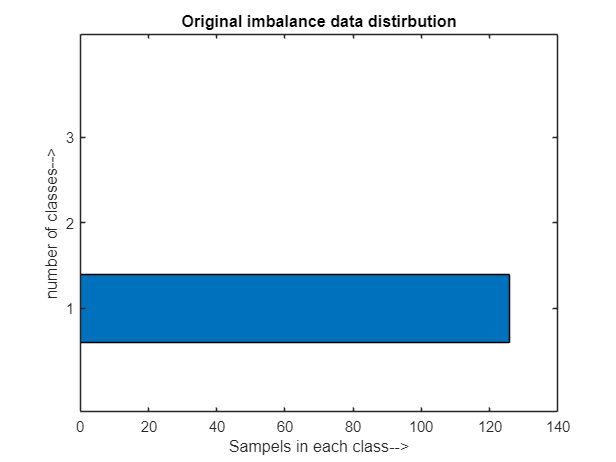

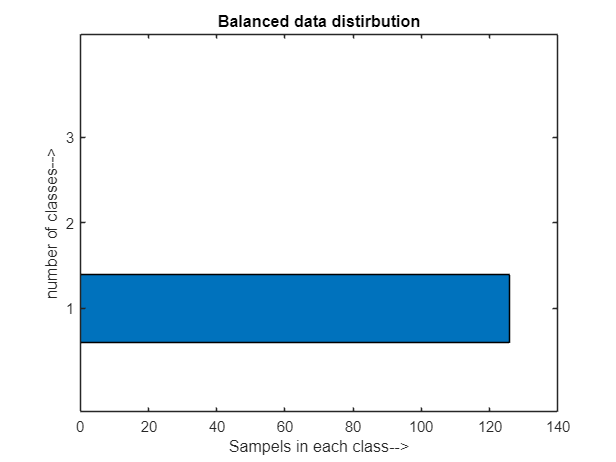

% Fix class imbalance with Synthetic Minority Over-sampling Technique (SMOTE)
balanced_emg_data = mySMOTE(emg_features, 5, sort(emg_features(:,end))); % unbalanced data, k neighbors, labels ordered/sorted


% Train classifier using 5 fold cross validation
emg_classifier = fitcdiscr(balanced_emg_data(:,1:10), balanced_emg_data(:,end),"DiscrimType","linear","CrossVal","on","KFold",5,"SaveMemory","on"); % LDA
save("trained_classifiers\emg_classifier.mat","emg_classifier");

% Accuracy
accuracy_first_fold = loss(emg_classifier.Trained{1}, balanced_emg_data(:,1:10), balanced_emg_data(:,end));
disp(['LDA 1st fold accuracy : ', num2str((1-accuracy_first_fold)*100), '%']);

LDA 1st fold accuracy : 100%


accuracy_second_fold = loss(emg_classifier.Trained{2}, balanced_emg_data(:,1:10), balanced_emg_data(:,end));
disp(['LDA 2nd fold accuracy : ', num2str((1-accuracy_second_fold)*100), '%']);

LDA 2nd fold accuracy : 100%


accuracy_third_fold = loss(emg_classifier.Trained{3}, balanced_emg_data(:,1:10), balanced_emg_data(:,end));
disp(['LDA 3rd fold accuracy : ', num2str((1-accuracy_third_fold)*100), '%']);

LDA 3rd fold accuracy : 100%


accuracy_fourth_fold = loss(emg_classifier.Trained{4}, balanced_emg_data(:,1:10), balanced_emg_data(:,end));
disp(['LDA 4th fold accuracy : ', num2str((1-accuracy_fourth_fold)*100), '%']);

LDA 4th fold accuracy : 100%


accuracy_fifth_fold = loss(emg_classifier.Trained{5}, balanced_emg_data(:,1:10), balanced_emg_data(:,end));
disp(['LDA 5th fold accuracy : ', num2str((1-accuracy_fifth_fold)*100), '%']);

LDA 5th fold accuracy : 100%



disp(['LDA average accuracy : ', num2str((1-(accuracy_first_fold+accuracy_second_fold+accuracy_third_fold+accuracy_fourth_fold+accuracy_fifth_fold)/5)*100), '%']);

LDA average accuracy : 100%


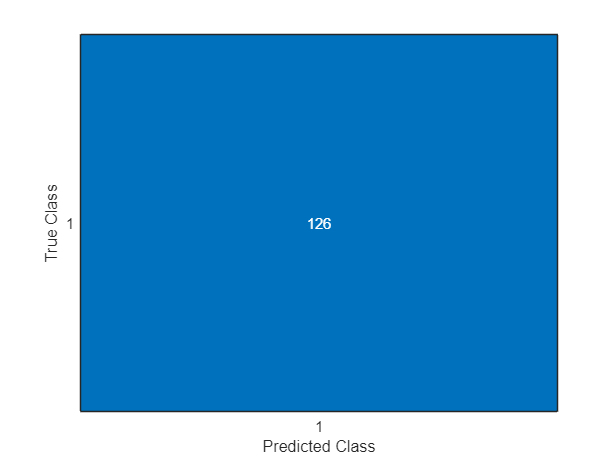


% Confusion matrix
predicted = predict(emg_classifier.Trained{1}, balanced_emg_data(:,1:10));
emg_confusion_matrix = confusionmat(balanced_emg_data(:,end), predicted);
confusionchart(emg_confusion_matrix)

fprintf("=======================================================================================")

[https://www.jmlr.org/papers/volume11/ojala10a/ojala10a.pdf](https://www.jmlr.org/papers/volume11/ojala10a/ojala10a.pdf) 

[https://www.sciencedirect.com/science/article/pii/S2213158214000485](https://www.sciencedirect.com/science/article/pii/S2213158214000485) 

Response time

N/A

Turtlebot3 and gazebo

N/A